clear
clc

loadSim

Loading file: D05_08_h05_Ed_Asbc_R01
Loading file: D05_08_h05_Ef_Ab_03H01_R01
Loading file: D05_08_h05_Ef_Asbc_R01
Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ed_As10H05_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Loading file: DC_bias
Elapsed time is 0.053798 seconds.
Data loaded


y = D05_08_h05_Ef_Asbc_R01.data(:,2);
u = D05_08_h05_Ef_Asbc_R01.data(:,5);
z = iddata(y, u, 0.05, 'Name', 'Pendulum');
z.OutputName = {'Pendulum position'};
z.OutputUnit = {'rad'};
z.InputName = {'Control Signal'};
z.Tstart = 0;
z.TimeUnit = 's';

FileName      = 'flywheel_extended_angle';        % File describing the model structure.
Order         = [1 1 3];             % Model orders [ny nu nx].
Parameters    = [9.81; 0.209; 0.18; 0.492; 0.05; 2.3e-4; 0.029; 0.027; 0.025; 1; 1.32e-6];   % Initial parameters. %g,Mf,lf,mp,lp,Jf,Jm,c_u,c_v
InitialStates = [0; 0; 0];              % Initial initial states.
Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum position'};
nlgr.OutputUnit = {'rad'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum position' 'Pendulum velocity' 'Flywheel velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'Gravity constant' 'Flywheel mass' ...
                      'flywheel length' 'pendulum mass' 'pendulum cog length' 'flywheel inertia' 'pendulum inertia' 'motor torque constant' 'back emf constant' 'motor resistance' 'dynamic friction torque'});
nlgr = setpar(nlgr, 'Unit', {'m/s^2' 'kg' 'm' 'kg' 'm' 'inertia' 'inertia' 'idk' 'idk' 'idk' 'idk'});
nlgr = setpar(nlgr, 'Minimum', {eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0)});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {20 2 0.5 3 0.5 inf inf 2 1 inf 1e-4});   % All parameters > 0.

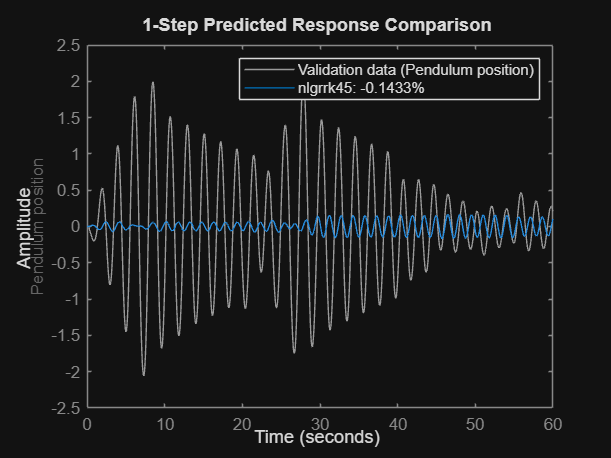

nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {true false false false false false false false false false false});

We finally use the Runge-Kutta 45 solver (ode45).

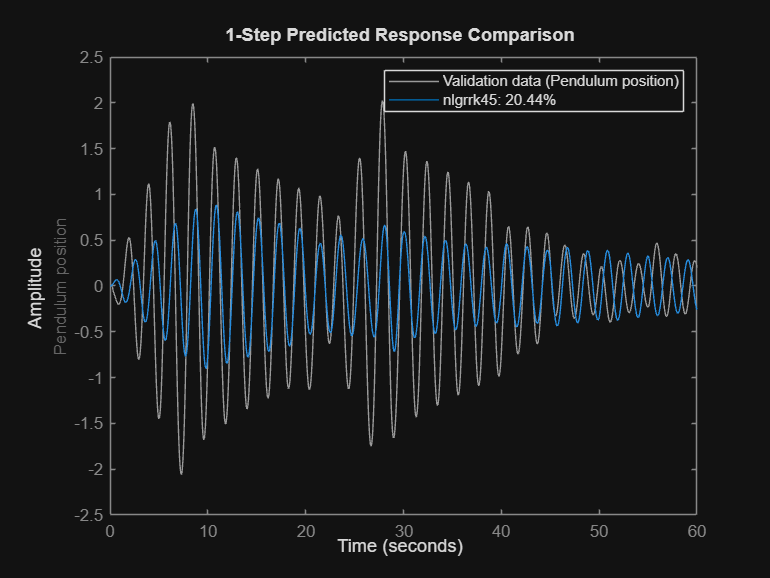

opt = nlgreyestOptions('Display', 'on');
trk45 = clock;
nlgrrk45 = nlgreyest(z, nlgrrk45, opt);   % Perform parameter estimation.
trk45 = etime(clock, trk45);
compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

fpe(nlgrrk45);

    0.4207



y = D06_05_h05_Ef_As05H05_R01.data(:,2);
u = D06_05_h05_Ef_As05H05_R01.data(:,5);
z2 = iddata(y, u, 0.05, 'Name', 'Pendulum');
z2.OutputName = {'Pendulum position'};
z2.OutputUnit = {'rad'};
z2.InputName = {'Control Signal'};
z2.Tstart = 0;
z2.TimeUnit = 's';


for i = 1:5
    % if i==1
    %     y = D06_05_h05_Ef_As03H02_R01.data(:,2:3);
    %     u = D06_05_h05_Ef_As03H02_R01.data(:,5);
    % elseif i==2
    %     y = D06_05_h05_Ef_As05H05_R01.data(:,2:3);
    %     u = D06_05_h05_Ef_As05H05_R01.data(:,5);
    % elseif i==3
    %     y = D06_05_h05_Ef_As07H02_R01.data(:,2:3);
    %     u = D06_05_h05_Ef_As07H02_R01.data(:,5);
    % elseif i==4
    %     y = D06_05_h05_Ef_As03H10_R01.data(:,2:3);
    %     u = D06_05_h05_Ef_As03H10_R01.data(:,5);
    % else
    %     y = D06_05_h05_Ef_As03H05_R01.data(:,2:3);
    %     u = D06_05_h05_Ef_As03H05_R01.data(:,5);
    % end
    % 
    % z = iddata(y, u, 0.05, 'Name', 'Pendulum');
    % z.OutputName = {'Pendulum position','Flywheel angular velocity'};
    % z.OutputUnit = {'rad','rad/s'};
    % z.InputName = {'Control Signal'};
    % z.Tstart = 0;
    % z.TimeUnit = 's';
    % nlgrrk45 = nlgreyest(z,nlgrrk45, opt)
    
    nlgrrk45 = nlgreyest(z,nlgrrk45, opt)
    nlgrrk45 = pem(z2,nlgrrk45, opt)
    nlgrrk45 = nlgreyest(z2,nlgrrk45, opt)
    nlgrrk45 = pem(z,nlgrrk45, opt)
    
    nlgrrk45.Parameters
    figure(i),clf;
        compare(z, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended_angle' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 1 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: 21.28%                                                  
FPE: 0.4119, MSE: 0.4051                                                        

Model Properties
